% =-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=
% Communication Systems
% Computer Assignment 3 : (Transmitter – Receiver – Single Tone Modulation)
% Mohammad Mahdi Abdolhosseini
% Student Number: 810 198 434
% Fall 2021
% =-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=
clc; clear; close all;

# `Transmitter`

## `Phase Modulation`

### `Part 3:`

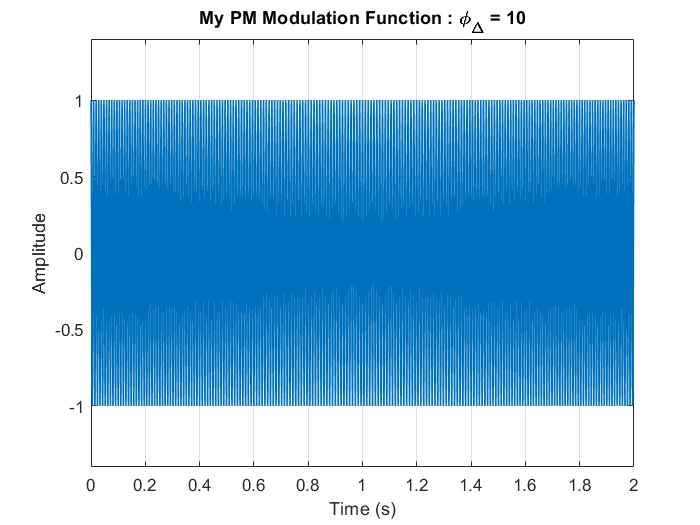

fs = 10000; % 10kHz
ts = 1 / fs;
t = 0 : ts : 10 - ts;

mt = sin(pi*t);

Ac = 1;
fc = 100; % 100Hz
phi_delta = 10;

mt_pm = pm(mt, Ac, phi_delta, fc, t);
plot(t, mt_pm, 'linewidth', 1);
title('My PM Modulation Function : \phi_\Delta = 10');
xlabel('Time (s)');
ylabel('Amplitude');
set(gca,'xtick', 0 : 0.2 : 10, 'xlim', [0,2]);
set(gca,'ytick', -2 : 0.5 : 2, 'ylim', [-1.4,1.4]);
grid on;

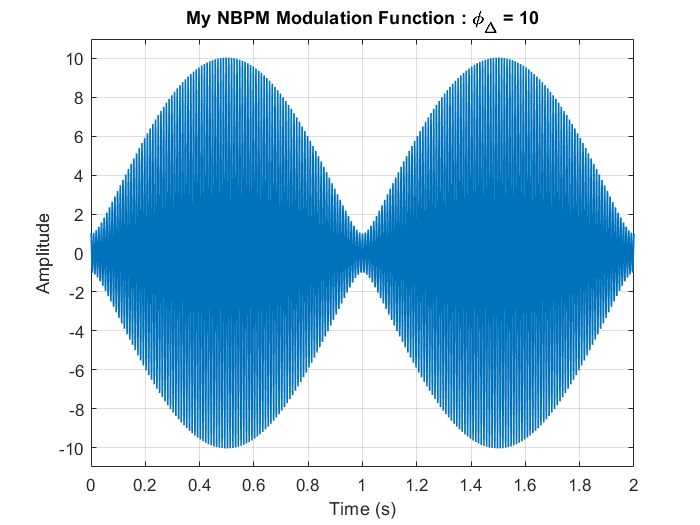


mt_nbpm = nbpm(mt, Ac, phi_delta, fc, t);
plot(t, mt_nbpm, 'linewidth', 1);
title('My NBPM Modulation Function : \phi_\Delta = 10');
xlabel('Time (s)');
ylabel('Amplitude');
set(gca,'xtick', 0 : 0.2 : 10, 'xlim', [0,2]);
set(gca,'ytick', -10 : 2 : 10, 'ylim', [-11,11]);
grid on;


error_NBPM = immse(mt_pm,mt_nbpm)

error_NBPM = 25.8112

### `Part 4:`

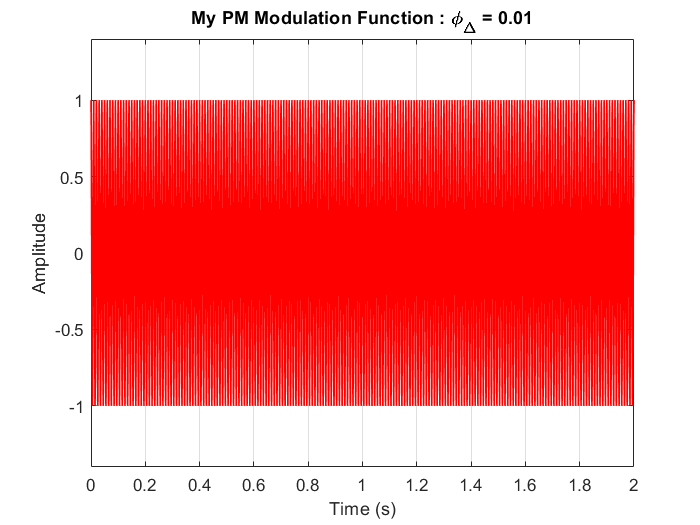

phi_delta = 0.01;

mt_pm = pm(mt, Ac, phi_delta, fc, t);
plot(t, mt_pm, 'r', 'linewidth', 1);
title('My PM Modulation Function : \phi_\Delta = 0.01');
xlabel('Time (s)');
ylabel('Amplitude');
set(gca,'xtick', 0 : 0.2 : 10, 'xlim', [0,2]);
set(gca,'ytick', -2 : 0.5 : 2, 'ylim', [-1.4,1.4]);
grid on;

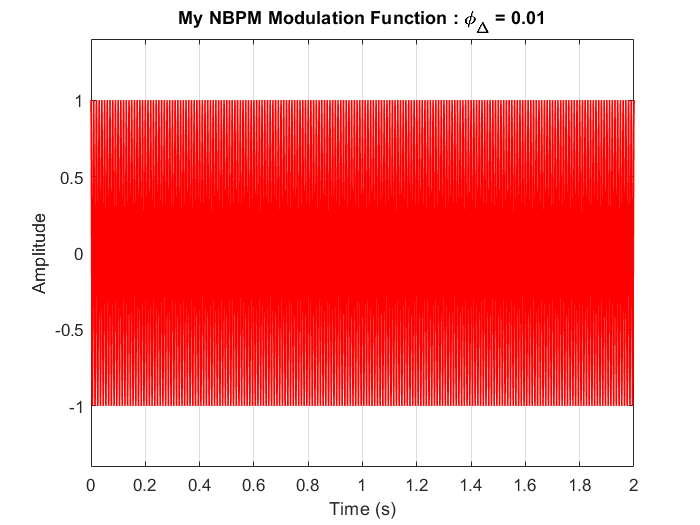


mt_nbpm = nbpm(mt, Ac, phi_delta, fc, t);
plot(t, mt_nbpm, 'r', 'linewidth', 1);
title('My NBPM Modulation Function : \phi_\Delta = 0.01');
xlabel('Time (s)');
ylabel('Amplitude');
set(gca,'xtick', 0 : 0.2 : 10, 'xlim', [0,2]);
set(gca,'ytick', -2 : 0.5 : 2, 'ylim', [-1.4,1.4]);
grid on;


error_NBPM = immse(mt_pm,mt_nbpm)

error_NBPM = 4.6875e-10

### `Part 5:6:`

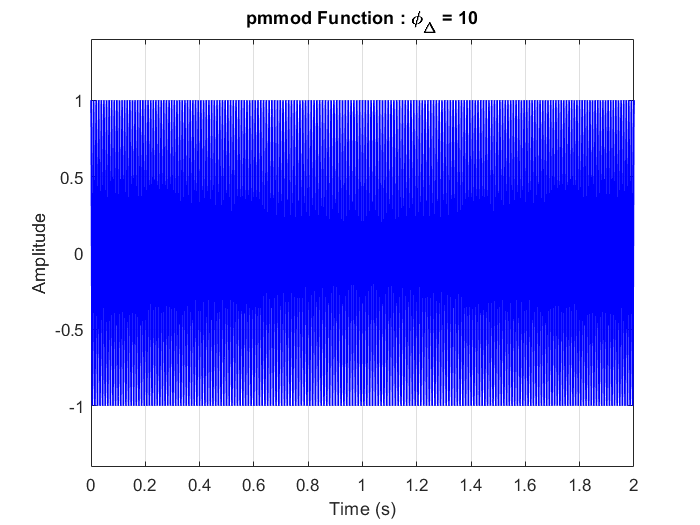

phi_delta = 10;

mt_pmmod = pmmod(mt, fc, fs, phi_delta);
plot(t, mt_pmmod, 'b', 'linewidth', 1);
title('pmmod Function : \phi_\Delta = 10');
xlabel('Time (s)');
ylabel('Amplitude');
set(gca,'xtick', 0 : 0.2 : 10, 'xlim', [0,2]);
set(gca,'ytick', -2 : 0.5 : 2, 'ylim', [-1.4,1.4]);
grid on;


mt_pm = pm(mt, Ac, phi_delta, fc, t);
error_pmmod_pm = immse(mt_pmmod, mt_pm)

error_pmmod_pm = 0

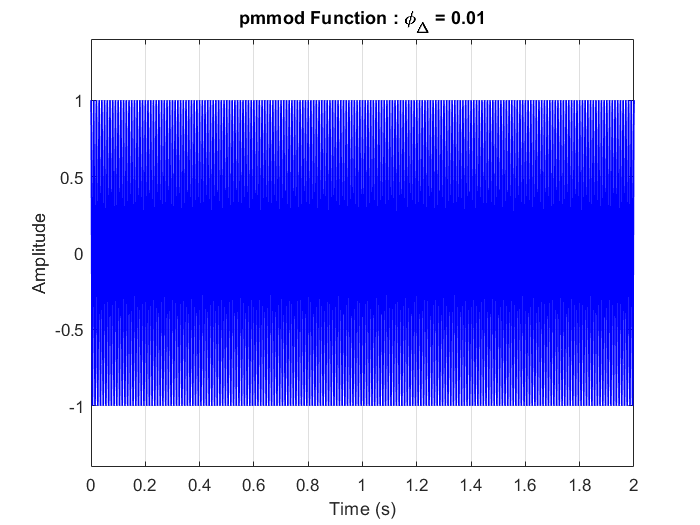


% =-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=

phi_delta = 0.01;

mt_pmmod = pmmod(mt, fc, fs, phi_delta);
plot(t, mt_pmmod, 'b', 'linewidth', 1);
title('pmmod Function : \phi_\Delta = 0.01');
xlabel('Time (s)');
ylabel('Amplitude');
set(gca,'xtick', 0 : 0.2 : 10, 'xlim', [0,2]);
set(gca,'ytick', -2 : 0.5 : 2, 'ylim', [-1.4,1.4]);
grid on;


mt_pm = pm(mt, Ac, phi_delta, fc, t);
error_pmmod_pm = immse(mt_pmmod, mt_pm)

error_pmmod_pm = 0

## `Frequency Modulation`

### `Part 8:`

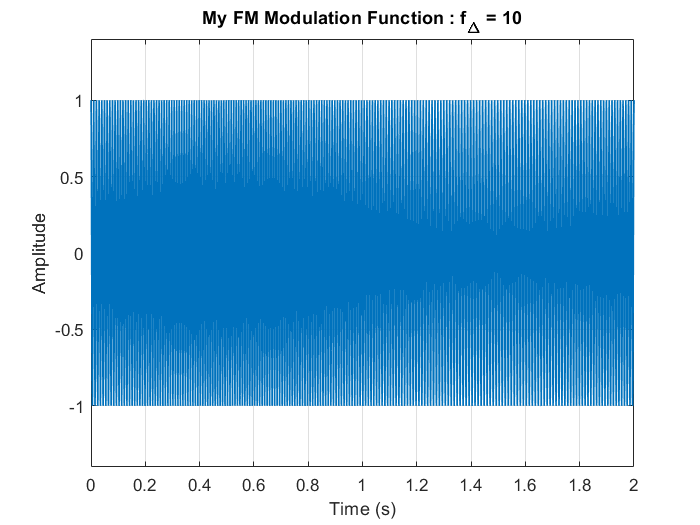

f_delta = 10;

mt_fm = fm(mt, Ac, f_delta, fc, t);
plot(t, mt_fm, 'linewidth', 1);
title('My FM Modulation Function : f_\Delta = 10');
xlabel('Time (s)');
ylabel('Amplitude');
set(gca,'xtick', 0 : 0.2 : 10, 'xlim', [0,2]);
set(gca,'ytick', -2 : 0.5 : 2, 'ylim', [-1.4,1.4]);
grid on;

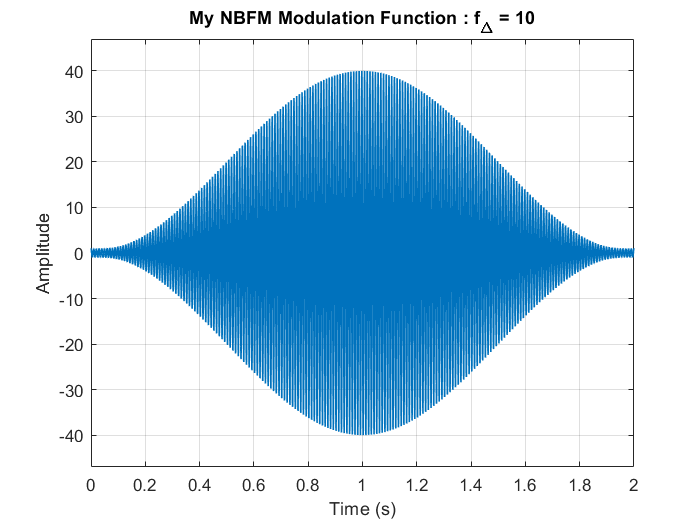


mt_nbfm = nbfm(mt, Ac, f_delta, fc, t);
plot(t, mt_nbfm, 'linewidth', 1);
title('My NBFM Modulation Function : f_\Delta = 10');
xlabel('Time (s)');
ylabel('Amplitude');
set(gca,'xtick', 0 : 0.2 : 10, 'xlim', [0,2]);
set(gca,'ytick', -50 : 10 : 50, 'ylim', [-47,47]);
grid on;


error_NBFM = immse(mt_fm,mt_nbfm)

error_NBFM = 297.3367

### `Part 9:`

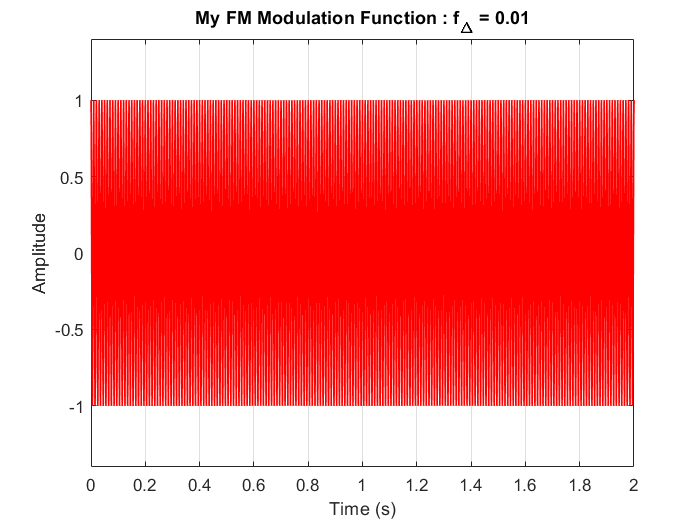

f_delta = 0.01;

mt_fm = fm(mt, Ac, f_delta, fc, t);
plot(t, mt_fm, 'r', 'linewidth', 1);
title('My FM Modulation Function : f_\Delta = 0.01');
xlabel('Time (s)');
ylabel('Amplitude');
set(gca,'xtick', 0 : 0.2 : 10, 'xlim', [0,2]);
set(gca,'ytick', -2 : 0.5 : 2, 'ylim', [-1.4,1.4]);
grid on;

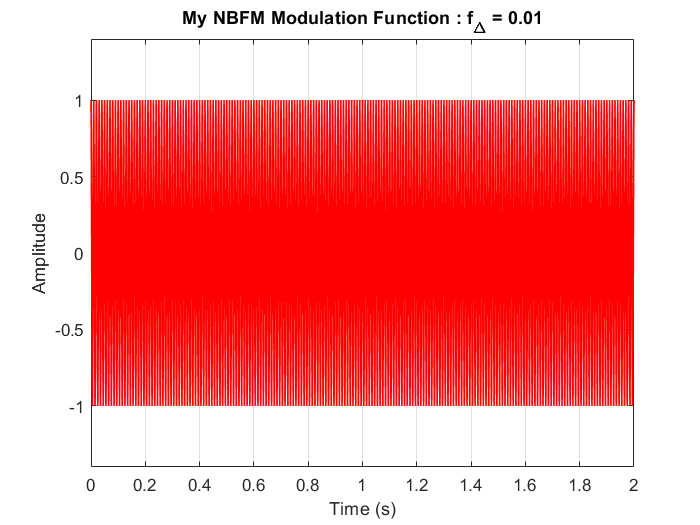


mt_nbfm = nbfm(mt, Ac, f_delta, fc, t);
plot(t, mt_nbfm, 'r', 'linewidth', 1);
title('My NBFM Modulation Function : f_\Delta = 0.01');
xlabel('Time (s)');
ylabel('Amplitude');
set(gca,'xtick', 0 : 0.2 : 10, 'xlim', [0,2]);
set(gca,'ytick', -2 : 0.5 : 2, 'ylim', [-1.4,1.4]);
grid on;


error_NBFM = immse(mt_fm,mt_nbfm)

error_NBFM = 8.7494e-08

### `Part 10:11:`

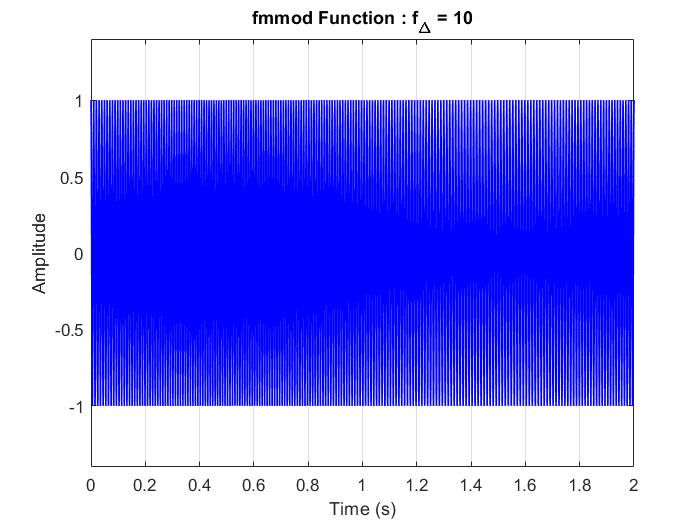

f_delta = 10;

mt_fmmod = fmmod(mt, fc, fs, f_delta);
plot(t, mt_fmmod, 'b', 'linewidth', 1);
title('fmmod Function : f_\Delta = 10');
xlabel('Time (s)');
ylabel('Amplitude');
set(gca,'xtick', 0 : 0.2 : 10, 'xlim', [0,2]);
set(gca,'ytick', -2 : 0.5 : 2, 'ylim', [-1.4,1.4]);
grid on;


mt_fm = fm(mt, Ac, f_delta, fc, t);
error_fmmod_fm = immse(mt_fmmod, mt_fm)

error_fmmod_fm = 2.4674e-06

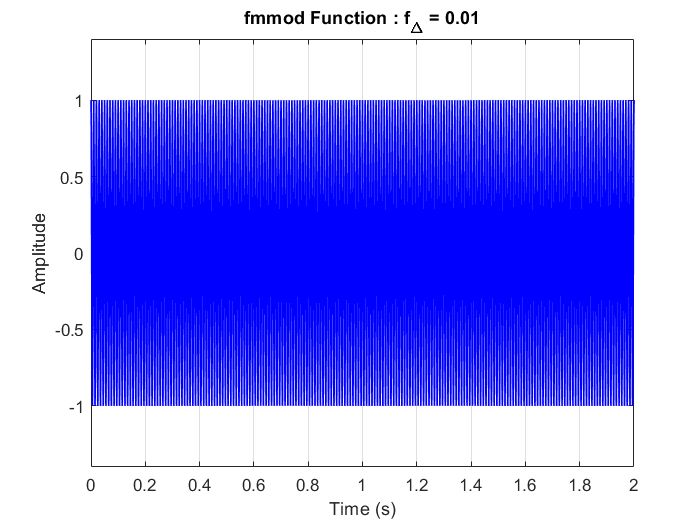


% =-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=

f_delta = 0.01;

mt_fmmod = fmmod(mt, fc, fs, f_delta);
plot(t, mt_fmmod, 'b', 'linewidth', 1);
title('fmmod Function : f_\Delta = 0.01');
xlabel('Time (s)');
ylabel('Amplitude');
set(gca,'xtick', 0 : 0.2 : 10, 'xlim', [0,2]);
set(gca,'ytick', -2 : 0.5 : 2, 'ylim', [-1.4,1.4]);
grid on;


mt_fm = fm(mt, Ac, f_delta, fc, t);
error_fmmod_fm = immse(mt_fmmod, mt_fm)

error_fmmod_fm = 2.4674e-12

### `Part 12:`

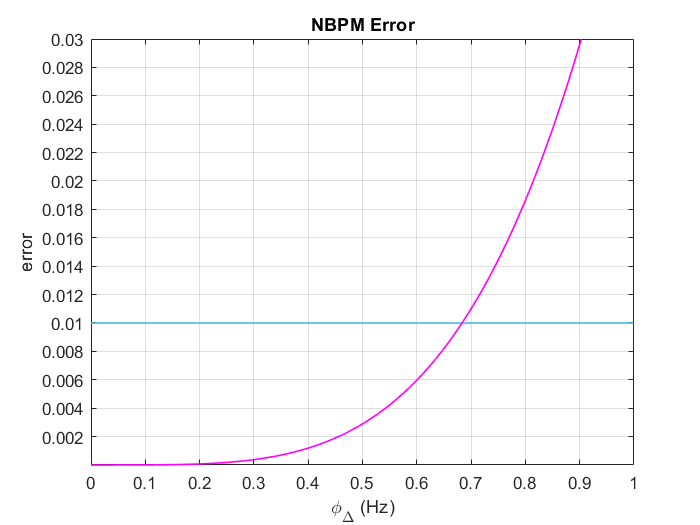

delta = 0 : 0.001 : 1 - 0.001;
error_NBPM = [];
error_NBFM = [];

for idelta = delta
    mti_pm = pm(mt, Ac, idelta, fc, t);
    mti_nbpm = nbpm(mt, Ac, idelta, fc, t);
    error_NBPM = [error_NBPM, immse(mti_pm, mti_nbpm)];

    mti_fm = fm(mt, Ac, idelta, fc, t);
    mti_nbfm = nbfm(mt, Ac, idelta, fc, t);
    error_NBFM = [error_NBFM, immse(mti_fm, mti_nbfm)];
end

plot(delta, 0.01*ones(length(delta)), delta, error_NBPM, 'm', 'linewidth', 1);
title('NBPM Error');
xlabel('\phi_\Delta (Hz)');
ylabel('error');
set(gca,'xtick', 0 : 0.1 : 1 , 'xlim', [0, 1]);
set(gca,'ytick', 0.002 : 0.002 : 0.03 , 'ylim', [0,0.03]);
grid on;

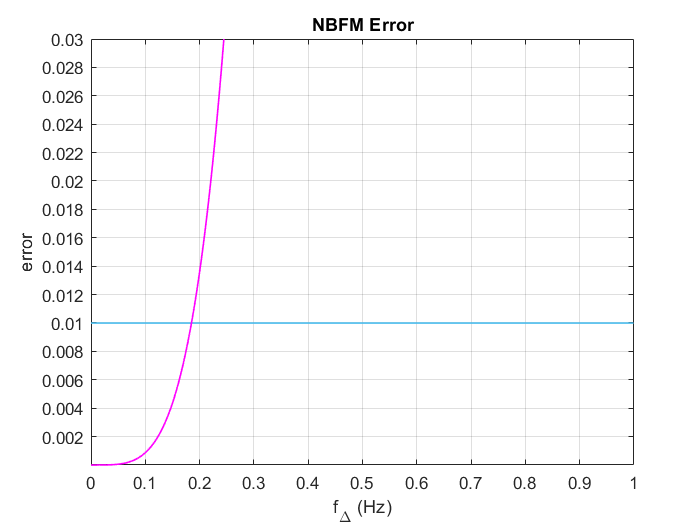


plot(delta, 0.01*ones(length(delta)), delta, error_NBFM, 'm', 'linewidth', 1);
title('NBFM Error');
xlabel('f_\Delta (Hz)');
ylabel('error');
set(gca,'xtick', 0 : 0.1 : 1 , 'xlim', [0, 1]);
set(gca,'ytick', 0.002 : 0.002 : 0.03 , 'ylim', [0,0.03]);
grid on;

# `Receiver`

## `Frequency deModulation`

### `Part 3:4:`

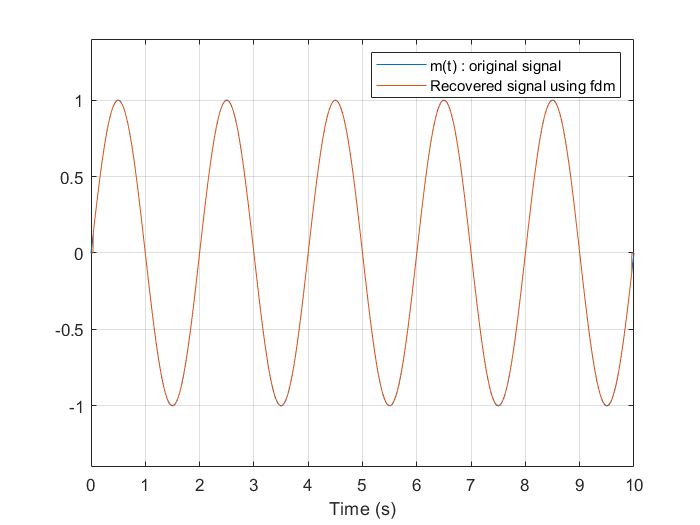

f_delta = 10;
mt_fm = fm(mt, Ac, f_delta, fc, t);
mt_fdm = fdm(mt_fm, Ac, f_delta, fs);

plot(t, mt, t, mt_fdm);
legend('m(t) : original signal', 'Recovered signal using fdm');
xlabel('Time (s)');
set(gca,'xtick', 0 : 1 : 10, 'xlim', [0,10]);
set(gca,'ytick', -2 : 0.5 : 2, 'ylim', [-1.4,1.4]);
grid on;


error_fdm = immse(mt_fdm, mt)

error_fdm = 4.4507e-05


mt_fmdemod = fmdemod(mt_fm,fc,fs,f_delta);
error_fmdemod_fdm = immse(mt_fdm, mt_fmdemod)

error_fmdemod_fdm = 4.4543e-05

## `Phase deModulation`

### `Part 7:8:`

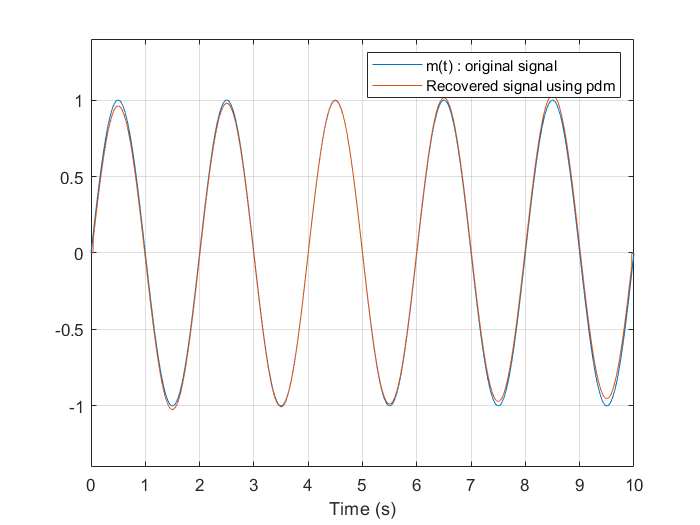

phi_delta = 3;
mt_pm = pm(mt, Ac, phi_delta, fc, t);
mt_pdm = pdm(mt_pm, Ac, phi_delta, fs, t);

plot(t, mt, t, mt_pdm);
legend('m(t) : original signal', 'Recovered signal using pdm');
xlabel('Time (s)');
set(gca,'xtick', 0 : 1 : 10, 'xlim', [0,10]);
set(gca,'ytick', -2 : 0.5 : 2, 'ylim', [-1.4,1.4]);
grid on;


error_pdm = immse(mt_pdm, mt)

error_pdm = 7.2883e-04


mt_pmdemod = pmdemod(mt_pm, fc, fs, phi_delta);
error_pmdemod_pdm = immse(mt_pdm, mt_pmdemod)

error_pmdemod_pdm = 7.2883e-04

# `Tune Modulation`

### `Part 1:`

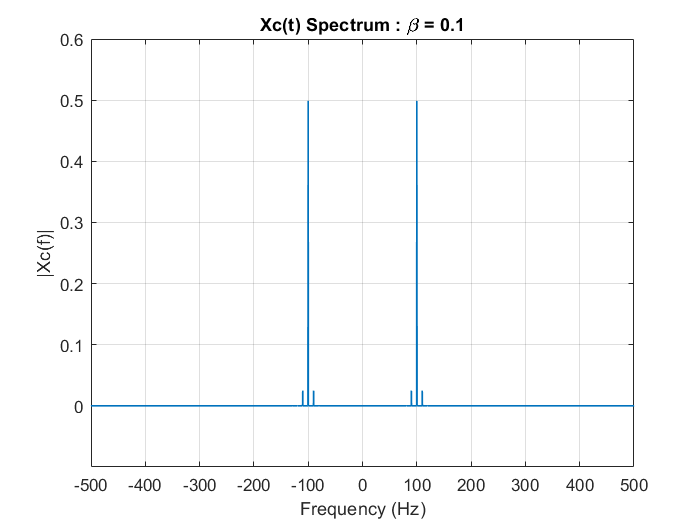

beta = 0.1;
mt = sin(20*pi*t);

xc = Ac * cos(2*pi*fc*t + beta*mt);

Xcf = fftshift(fft(xc));
l_Xcf = length(Xcf);
abs_Xcf = abs(Xcf/l_Xcf);

f1 = -fs/2 : fs/l_Xcf : fs/2 - fs/l_Xcf;

plot(f1, abs_Xcf, 'linewidth', 1);
title('Xc(t) Spectrum : \beta = 0.1');
xlabel('Frequency (Hz)');
ylabel('|Xc(f)|');
set(gca,'xtick', -500 : 100 : 500, 'xlim', [-500,500]);
set(gca,'ytick', 0 : 0.1 : 1, 'ylim', [-0.1,0.6]);
grid on;

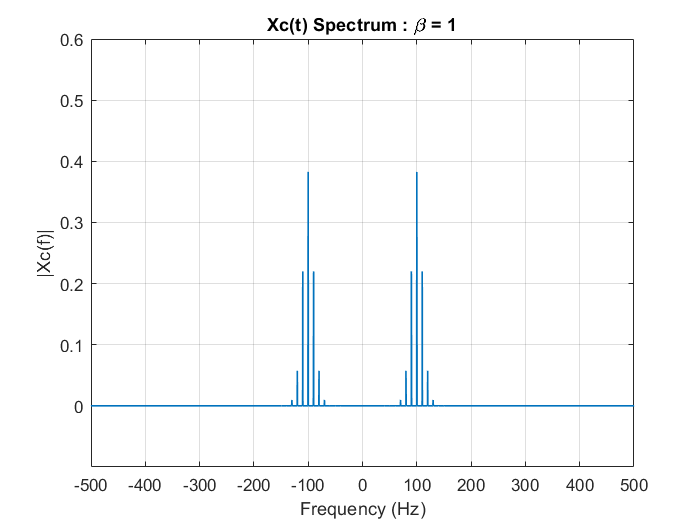



beta = 1;

xc = Ac * cos(2*pi*fc*t + beta*mt);

Xcf = fftshift(fft(xc));
l_Xcf = length(Xcf);
abs_Xcf = abs(Xcf/l_Xcf);

f1 = -fs/2 : fs/l_Xcf : fs/2 - fs/l_Xcf;

plot(f1, abs_Xcf, 'linewidth', 1);
title('Xc(t) Spectrum : \beta = 1');
xlabel('Frequency (Hz)');
ylabel('|Xc(f)|');
set(gca,'xtick', -500 : 100 : 500, 'xlim', [-500,500]);
set(gca,'ytick', 0 : 0.1 : 1, 'ylim', [-0.1,0.6]);
grid on;

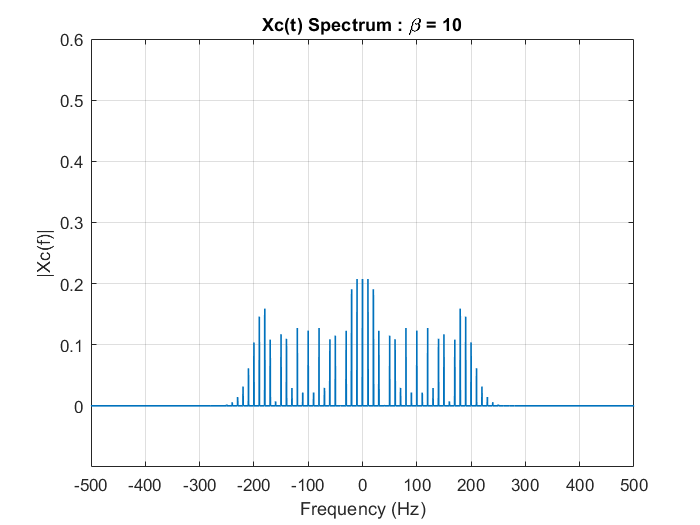



beta = 10;

xc = Ac * cos(2*pi*fc*t + beta*mt);

Xcf = fftshift(fft(xc));
l_Xcf = length(Xcf);
abs_Xcf = abs(Xcf/l_Xcf);

f1 = -fs/2 : fs/l_Xcf : fs/2 - fs/l_Xcf;

plot(f1, abs_Xcf, 'linewidth', 1);
title('Xc(t) Spectrum : \beta = 10');
xlabel('Frequency (Hz)');
ylabel('|Xc(f)|');
set(gca,'xtick', -500 : 100 : 500, 'xlim', [-500,500]);
set(gca,'ytick', 0 : 0.1 : 1, 'ylim', [-0.1,0.6]);
grid on;

# `Transmitter Functions:`

### `Part 1: pm()`

function Xc = pm(x, Ac, phi_delta, fc, t)
    n = max(abs(x));
    phi_t = phi_delta * x/n;
    Xc = Ac*cos(2*pi*fc*t + phi_t);
end

### `Part 2: nbpm()`

function Xc = nbpm(x, Ac, phi_delta, fc, t)
    n = max(abs(x));
    phi_t = phi_delta * x/n;
    Xc = Ac*cos(2*pi*fc*t) - Ac*phi_t.*sin(2*pi*fc*t);
end

### `Part 7: fm()`

function Xc = fm(x, Ac, f_delta, fc, t)
    n = max(abs(x));
    phi_t = 2 * pi * f_delta * cumtrapz(t, x/n);
    Xc = Ac*cos(2*pi*fc*t + phi_t);
end

### `Part 7: nbfm()`

function Xc = nbfm(x, Ac, f_delta, fc, t)
    n = max(abs(x));
    phi_t = 2 * pi * f_delta * cumtrapz(t, x/n);
    Xc = Ac*cos(2*pi*fc*t) - Ac*phi_t.*sin(2*pi*fc*t);
end

# `Receiver Functions:`

### `Part 2: fdm()`

function x = fdm(Xc, Ac, f_delta, fs)
    dXc = fs * gradient(Xc); % d/dt
    [EdXc,] = envelope(dXc,1000);   % Envelope Detector
    removeDC = EdXc - mean(EdXc);
    k = 2 * pi * f_delta * Ac;
    x = removeDC / k;
    
    % for smoother edges and error reduction
    x(1, 1:round(fs/25)) = 0;
    x(1, length(x) - round(fs/25) : length(x)) = 0;   
end

### `Part 6: pdm()`

function x = pdm(Xc, Ac, phi_delta, fs, t)
    dXc = fs * gradient(Xc); % d/dt
    [EdXc,] = envelope(dXc,1000);   % Envelope Detector
    removeDC = EdXc - mean(EdXc);
    k = phi_delta * Ac;
    x = removeDC / k;
    x = cumtrapz(t, x);   % integral
    
    % for smoother edges and error reduction
    x(1, 1:round(fs/25)) = 0;
    x(1, length(x) - round(fs/25) : length(x)) = 0;   
end